% x = sym("x_%d", [3, 4])
x = [0, 1;
     0, 1;
     0, 1];

% y = 5*x.^2+7*x;
y = [0, 285.6332;
     0, -106.2121;
     -6000.0, -5836.5273]

y = 1.0e+03 *

         0    0.2856
         0   -0.1062
   -6.0000   -5.8365


% y_prime = 10*x+7;
y_prime = [340, 36.3625;
             0, 26.9951;
             0, -1026.0446]

y_prime = 1.0e+03 *

    0.3400    0.0364
         0    0.0270
         0   -1.0260


% t = sym("t_%d", [3, 5])
t = [0, 0.1, 0.2, 0.3, 0.4, 0.5, 0.6, 0.7, 0.8, 0.9, 1.0;
     0, 0.1, 0.2, 0.3, 0.4, 0.5, 0.6, 0.7, 0.8, 0.9, 1.0;
     0, 0.1, 0.2, 0.3, 0.4, 0.5, 0.6, 0.7, 0.8, 0.9, 1.0]

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


% y_true = 5*t.^2+7*t

% sub1 = repmat(reshape((x-x.')+x.'-diag(x), 1, length(x), length(x)), length(t), 1, 1);
[r, c1] = size(x);
[~, c2] = size(t);

x_prime_1 = reshape(repmat(x, 1, c1), r, c1, c1);
x_prime_mask = permute(repmat(eye(c1), 1, 1, r), [3, 1, 2]);
x_prime_2 = x_prime_1 - x_prime_mask.*x_prime_1;
x_prime = permute(repmat(x_prime_2, 1, 1, 1, c2), [1, 4, 2, 3]);

% sub2 = repmat(t, 1, length(x)*length(x));
% sub2 = reshape(sub2, length(t), length(x), length(x));
t_prime_1 = repmat(t, 1, 1, c1);
t_prime = reshape(repmat(t_prime_1, 1, 1, c1), r, c2, c1, c1);

% l_num = sub2-sub1-(sub2.*repmat(reshape(eye(length(x)), 1, length(x), length(x)), length(t), 1, 1))+repmat(reshape(eye(length(x)), 1, length(x), length(x)), length(t), 1, 1);
l_num_1 = t_prime - x_prime;
l_num_mask = permute(reshape(repmat(eye(c1), 1, 1, r*c2), c1, c1, r, c2), [3, 4, 1, 2]);
l_num_2 = l_num_1 - l_num_mask.*l_num_1 + l_num_mask

l_num_2 = l_num_2(:,:,1,1) =

     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1


l_num_2(:,:,2,1) =

   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0
   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0
   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0


l_num_2(:,:,1,2) =

         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


l_num_2(:,:,2,2) =

     1     1     1     1     1     1 

l_num = squeeze(prod(l_num_2, 3));

% l_den = repmat(prod(x.'-x+eye(length(x)), 1), length(t), 1)
l_den_1 = prod((permute(x_prime_1, [1, 3, 2])-x_prime_1)+x_prime_mask, 2);
l_den = repmat(l_den_1, [1, c2, 1]);

%l = l_num./l_den
l = l_num ./ l_den;

% l_prime = sum(1./(x.'-x+eye(length(x))), 1)-1
l_prime_1 = 1./(permute(x_prime_1, [1, 3, 2])-x_prime_1+x_prime_mask);
l_prime_2 = sum(l_prime_1, 2)-1;
l_prime = repmat(l_prime_2, [1, c2, 1]);

% function B
% B = (t-x.').*l.*l
x_prime_3 = permute(repmat(x, 1, 1, c2), [1, 3, 2]);
B = (t_prime_1 - x_prime_3).*l.*l;

% function A
% A = (1-2*(t-x.').*repmat(l_prime, length(t), 1)).*l.*l
A = (1-2*(t_prime_1 - x_prime_3).*l_prime).*l.*l;

% H = sum(repmat(y.', c2, 1).*A, 2)+sum(repmat(y_prime.', c2, 1).*B, 2)
A_prime = permute(repmat(y, 1, 1, c2), [1, 3, 2]).*A;
B_prime = permute(repmat(y_prime, 1, 1, c2), [1, 3, 2]).*B;
H = squeeze(sum(A_prime, 3) + sum(B_prime, 3));

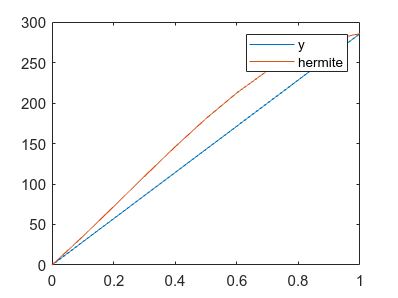

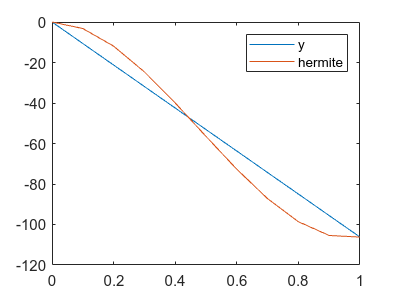

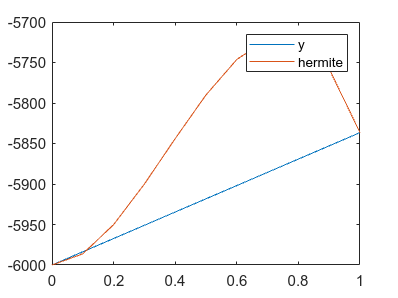

for i = 1:r
    figure;
    plot(x(i, :), y(i, :));
    hold on;
    %plot(x, y_prime);
    plot(t(i, :), H(i, :));
    % plot(t(i, :), y_true(i, :), "--")
    legend("y", "hermite")
end